clc;
clear;
close all;

%% ================= SIMULATION SETUP =================

dt   = 1;
Tend = 800;
t = 0:dt:Tend;
N = length(t);

Nc = 12;                % number of series cells

%% ================= CURRENT PROFILE (PULSE TEST) =================

I = zeros(1,N);

for k = 1:N
    if t(k) > 100 && t(k) <= 200
        I(k) = 12;
    elseif t(k) > 350 && t(k) <= 450
        I(k) = 8;
    else
        I(k) = 0;
    end
end

%% ================= CELL PARAMETERS =================

Q = 50;                 % Ah

R0_25 = 0.01;
R1_25 = 0.02;
C1_nom = 2000;

C1 = C1_nom*ones(Nc,1);

%% ================= THERMAL PARAMETERS =================

Tamb = 35;
Tcell = 35*ones(Nc,1);
Tlog  = zeros(Nc,N);     % store temperature history
Tlog(:,1) = Tcell;

Cth = 500;              % J/K
h = 1.2;

alpha_R = 0.015;

%% ================= STATES =================

SOC  = 0.9*ones(Nc,N);
Vrc  = zeros(Nc,N);
Vcell = zeros(Nc,N);
Vpack = zeros(1,N);

%% ================= OCV FUNCTION =================

OCV = @(soc) 3.0 + 1.2*soc;

%% ================= MAIN LOOP =================

for k = 1:N-1

    for c = 1:Nc

        % Temperature-dependent resistances
        R0c = R0_25*(1 + alpha_R*(25 - Tcell(c)));
        R1c = R1_25*(1 + alpha_R*(25 - Tcell(c)));
         Tlog(:,k+1) = Tcell;

        % SOC update
        SOC(c,k+1) = SOC(c,k) - (I(k)*dt)/(Q*3600);

        % RC update
        a = exp(-dt/(R1c*C1(c)));
        Vrc(c,k+1) = a*Vrc(c,k) + R1c*(1-a)*I(k);

        % Voltage
        Vcell(c,k) = OCV(SOC(c,k)) - I(k)*R0c - Vrc(c,k);

        % Thermal dynamics
        heat = I(k)^2 * R0c;
        cool = h*(Tcell(c) - Tamb);

        Tcell(c) = Tcell(c) + dt*(heat - cool)/Cth;

    end

    % Pack voltage
    Vpack(k) = sum(Vcell(:,k));

    % Weakest-cell cutoff
    if min(Vcell(:,k)) < 3.0
        disp("DISCHARGE CUT: cell undervoltage");
        I(k+1:end) = 0;
        break;
    end

end

%% ================= R0 ESTIMATION =================

k0 = find(t==101);

dV = mean(Vcell(:,k0)) - mean(Vcell(:,k0-1));
dI = I(k0) - I(k0-1);

R0_est = abs(dV/dI)

R0_est = 0.0085


%% ================= TAU FROM VRC =================

idx = find(t>=205 & t<=350);

Vrc_avg = mean(Vrc(:,idx),1);
tt = t(idx) - t(idx(1));

y = abs(Vrc_avg);
valid = y > max(y)*0.05;

y = y(valid);
tt = tt(valid);

p = polyfit(tt,log(y),1);
tau_est = -1/p(1)

tau_est = 33.8852

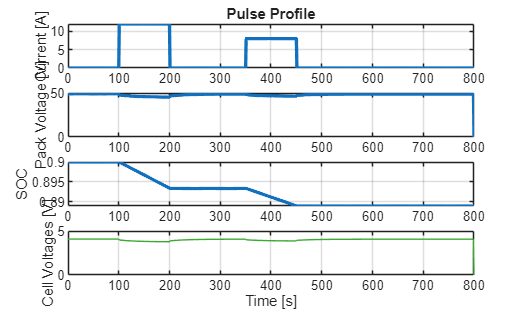

%% ================= EKF SOC ESTIMATOR =================

xhat = zeros(2,N);      % [SOC; Vrc]
xhat(:,1) = [0.85; 0]; % initial guess (wrong on purpose)

P = diag([1e-4  1e-3]);   % covariance

Qk = diag([1e-7  1e-5]);  % process noise
Rk = 1e-3;               % voltage noise variance

SOC_est = zeros(1,N);
SOC_est(1) = xhat(1,1);

for k = 1:N-1

    Ik = I(k);

    % use average temp for estimator
    R0e = R0_25*(1 + alpha_R*(25 - mean(Tlog(:,k))));
    R1e = R1_25*(1 + alpha_R*(25 - mean(Tlog(:,k))));
    a   = exp(-dt/(R1e*C1_nom));

    %% ---- Prediction ----

    f = [ xhat(1,k) - (Ik*dt)/(Q*3600);
          a*xhat(2,k) + R1e*(1-a)*Ik ];

    F = [ 1      0;
          0      a ];

    P = F*P*F' + Qk;

    %% ---- Measurement Update ----

    Vmeas = mean(Vcell(:,k));   % what sensors see

    % predicted voltage
    Vpred = OCV(f(1)) - Ik*R0e - f(2);

    % Jacobian dh/dx
    dOCVdSOC = 1.2;     % slope of OCV curve
    H = [ dOCVdSOC  -1 ];

    S = H*P*H' + Rk;
    K = P*H'/S;

    y = Vmeas - Vpred;

    xhat(:,k+1) = f + K*y;

    P = (eye(2)-K*H)*P;

    SOC_est(k+1) = xhat(1,k+1);

end

%% ================= PLOTS =================

figure;

subplot(4,1,1)
plot(t,I,'LineWidth',2)
ylabel('Current [A]')
grid on
title('Pulse Profile')

subplot(4,1,2)
plot(t,Vpack,'LineWidth',2)
ylabel('Pack Voltage [V]')
grid on

subplot(4,1,3)
plot(t,SOC(1,:),'LineWidth',2)
ylabel('SOC')
grid on

subplot(4,1,4)
plot(t,Vcell')
ylabel('Cell Voltages [V]')
xlabel('Time [s]')
grid on

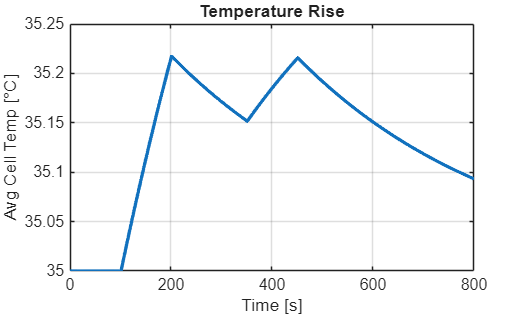


figure;
plot(t, mean(Tlog,1),'LineWidth',2)
xlabel('Time [s]')
ylabel('Avg Cell Temp [°C]')
grid on
title('Temperature Rise')

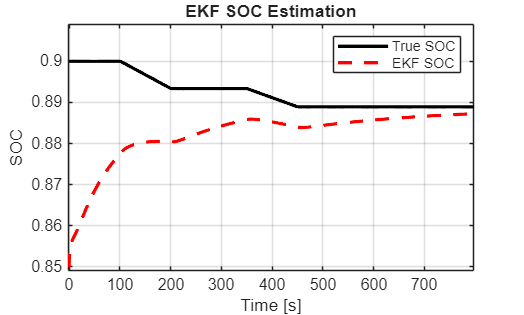



figure;
plot(t,SOC(1,:),'k','LineWidth',2); hold on;
plot(t,SOC_est,'r--','LineWidth',2);
legend('True SOC','EKF SOC');
grid on;
xlabel('Time [s]');
ylabel('SOC');
title('EKF SOC Estimation');